# Organize Hardware Train Data

clear vars; close all; clc;
warning('off','all')

% End at 5 seconds (assuming dt = 0.01)
idx_end = 201;
numObs = 15;

## Pick Training Data

[files,path] = uigetfile('*.mat',...
   'Select One or More Files', ...
   'MultiSelect', 'on');

## Conslidate Training Data

oData = consolidateSSMTrainData(path, files, center=false);

Load HW train Data f:  000%  |                                        | 0/27it [00:00:00<Inf:NaN:NaN, Inf it/s]


## Plot Raw Data

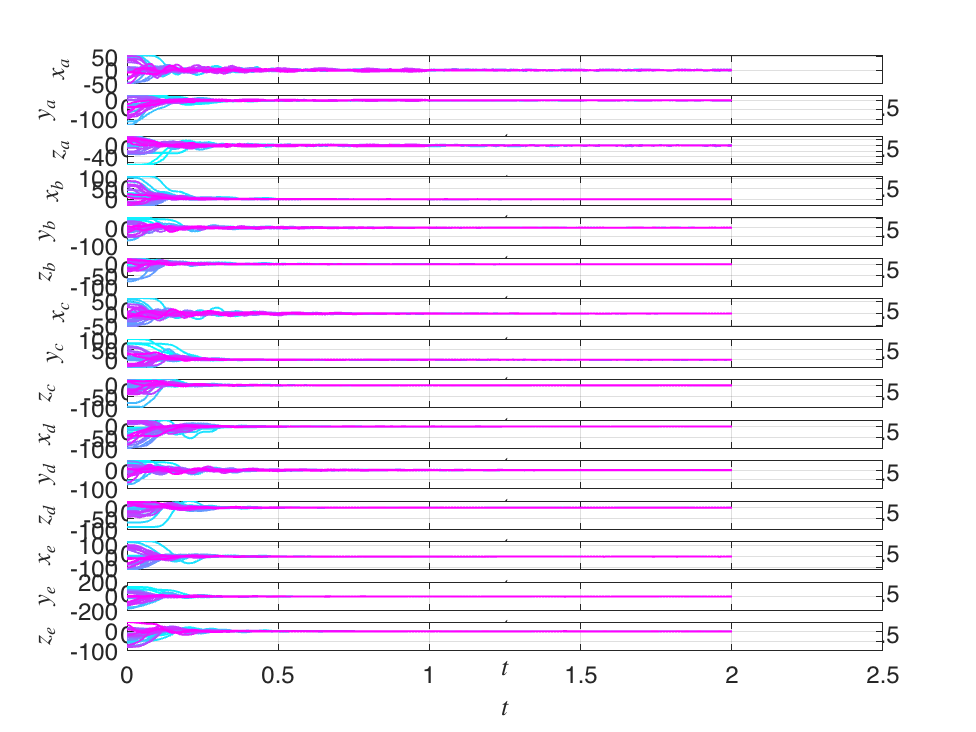

customFigure('subPlot',[numObs 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numObs
    subplot(numObs,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numObs
        subplot(numObs,1,iObs);
        plot(oData{iTraj,1}(1:idx_end),oData{iTraj,2}(iObs,1:idx_end),'Linewidth',1)
    end
end